# Ejercicio 01

Se tiene un vector de estrucuras en el que cada estructura almacena informacion detallada de un paciente. Se pide que los resultados de los tests sean representados en graficos para el correcto diagnostico del profesional de la salud, tambien se pide ordenar a cada paciente de acuerdo al monto a pagar en su cuenta.

paciente(1).nombre = 'John Montes';
paciente(1).cuenta = 127.00;
paciente(1).test = [79, 75, 73; 180, 178, 177.5; 220, 210, 205];

paciente(2).nombre = 'Ana Ledezma';
paciente(2).cuenta = 28.50;
paciente(2).test = [68, 70, 68; 118, 118, 119; 172, 170, 169];

paciente(3).nombre = 'Pedro Carpio';
paciente(3).cuenta = 85.50;
paciente(3).test = [100, 70, 85; 118, 158, 120; 145, 178, 145];

paciente

paciente = 1×3 struct array with fields:
    nombre
    cuenta
    test


## Representar los resultados en graficos

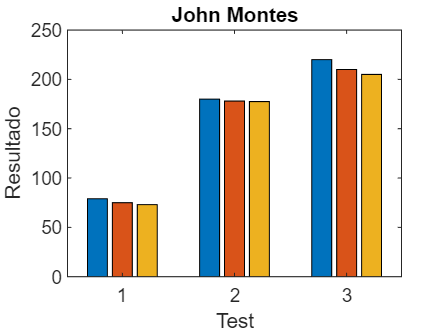

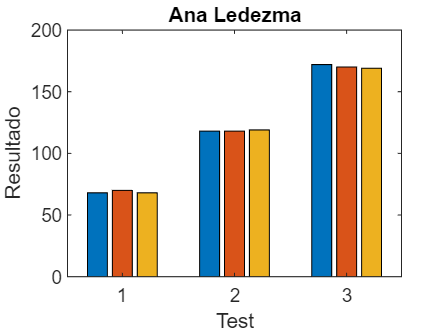

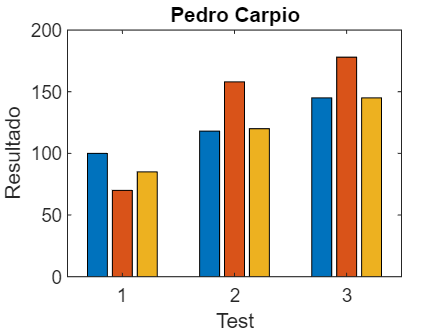

%Determinar el numero de pacientes
numPacientes = numel(paciente);
for p = 1:numPacientes
    figure
    bar(paciente(p).test)
    title(paciente(p).nombre)
    xlabel('Test')
    ylabel('Resultado')
end

## Ordenar los pacientes de acuerdo al monto a pagar

%Obtener las cuentas de los pacientes en un vector auxiliar
%Inicializar el vector auxiliar

cuentas = zeros(1,length(paciente));
for i = 1:length(paciente)
    cuentas(i) = paciente(i).cuenta;
end
cuentas

cuentas =   127.0000   28.5000   85.5000


Extraer los indices y ordenarlos de forma descendente

%Ordenar el vector auxiliar y obtener los indices correspondientes
[~, indices] = sort(cuentas); %Solo nos interesa guardar los indices

Reordenar el vector de estructuras

pacietesOrdenados = paciente(indices)

pacietesOrdenados = 1×3 struct array with fields:
    nombre
    cuenta
    test
